clear; clc; close all;

restoredefaultpath;
addpath("../spm/"); % Add path for SPM
spm('defaults','FMRI');
spm_jobman('initcfg');


## DCM for fMRI - 1st level (Attention)

saveDirGLM = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM1_attention/attention/GLM/';
mkdir(saveDirGLM); 


load("../SPM1_attention/attention/factors.mat"); 


## GLM specification

clear matlabbatch;
matlabbatch{1}.spm.stats.fmri_spec.dir = {saveDirGLM};
matlabbatch{1}.spm.stats.fmri_spec.timing.units = 'scans';
matlabbatch{1}.spm.stats.fmri_spec.timing.RT = 3.22;
matlabbatch{1}.spm.stats.fmri_spec.timing.fmri_t = 16;
matlabbatch{1}.spm.stats.fmri_spec.timing.fmri_t0 = 8;

% Get scans
scansStruct = dir("../SPM1_attention/attention/functional/snffM00587_*.img");
scansList = strcat({scansStruct.folder}', repmat({'/'},length(scansStruct),1),{scansStruct.name}',repmat({',1'},length(scansStruct),1));

matlabbatch{1}.spm.stats.fmri_spec.sess.scans = scansList;

% Add Experimental conditions
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).name = 'Photic';
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).onset = [att natt stat];
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).duration = 10;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).tmod = 0;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).pmod = struct('name', {}, 'param', {}, 'poly', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(1).orth = 1;

matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).name = 'Motion';
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).onset = [att natt];
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).duration = 10;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).tmod = 0;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).pmod = struct('name', {}, 'param', {}, 'poly', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(2).orth = 1;

matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).name = 'Attention';
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).onset = att;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).duration = 10;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).tmod = 0;
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).pmod = struct('name', {}, 'param', {}, 'poly', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.cond(3).orth = 1;

% Misc - set to default
matlabbatch{1}.spm.stats.fmri_spec.sess.multi = {''};
matlabbatch{1}.spm.stats.fmri_spec.sess.regress = struct('name', {}, 'val', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.multi_reg = {''};
matlabbatch{1}.spm.stats.fmri_spec.sess.hpf = 128;
matlabbatch{1}.spm.stats.fmri_spec.fact = struct('name', {}, 'levels', {});
matlabbatch{1}.spm.stats.fmri_spec.bases.hrf.derivs = [0 0];
matlabbatch{1}.spm.stats.fmri_spec.volt = 1;
matlabbatch{1}.spm.stats.fmri_spec.global = 'None';
matlabbatch{1}.spm.stats.fmri_spec.mthresh = 0.8;
matlabbatch{1}.spm.stats.fmri_spec.mask = {''};
matlabbatch{1}.spm.stats.fmri_spec.cvi = 'AR(1)';

% GLM estimate
matlabbatch{2}.spm.stats.fmri_est.spmmat = {fullfile(saveDirGLM, 'SPM.mat')};
matlabbatch{2}.spm.stats.fmri_est.write_residuals = 0;
matlabbatch{2}.spm.stats.fmri_est.method.Classical = 1;

spm_jobman('run',matlabbatch);



------------------------------------------------------------------------
15-Jul-2025 16:28:40 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 16:28:40 - Running 'fMRI model specification'
SPM25: spm_fMRI_design                             16:28:44 - 15/07/2025
Saving fMRI design                      :               ...SPM.mat saved

SPM25: spm_fmri_spm_ui                             16:28:44 - 15/07/2025
Mapping files                           :                        ...done
Calculating globals                     :                        ...done
Saving SPM configuration                :               ...SPM.mat saved
Saving SPM configuration                :               ...SPM.mat saved
Completed                               :          16:28:53 - 15/07/2025
15-Jul-2025 16:28:53 - Do

## Add contrasts

clear matlabbatch;
matlabbatch{1}.spm.stats.con.spmmat = {fullfile(saveDirGLM,'SPM.mat')};

matlabbatch{1}.spm.stats.con.consess{1}.fcon.name = 'Effects of interest';
matlabbatch{1}.spm.stats.con.consess{1}.fcon.weights = eye(3);
matlabbatch{1}.spm.stats.con.consess{1}.fcon.sessrep = 'none';

matlabbatch{1}.spm.stats.con.consess{2}.tcon.name = 'Photic';
matlabbatch{1}.spm.stats.con.consess{2}.tcon.weights = [1 0 0];
matlabbatch{1}.spm.stats.con.consess{2}.tcon.sessrep = 'none';

matlabbatch{1}.spm.stats.con.consess{3}.tcon.name = 'Motion';
matlabbatch{1}.spm.stats.con.consess{3}.tcon.weights = [0 1 0];
matlabbatch{1}.spm.stats.con.consess{3}.tcon.sessrep = 'none';

matlabbatch{1}.spm.stats.con.consess{4}.tcon.name = 'Attention';
matlabbatch{1}.spm.stats.con.consess{4}.tcon.weights = [0 0 1];
matlabbatch{1}.spm.stats.con.consess{4}.tcon.sessrep = 'none';

matlabbatch{1}.spm.stats.con.delete = 0;
spm_jobman('run',matlabbatch);



------------------------------------------------------------------------
15-Jul-2025 16:29:13 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 16:29:14 - Running 'Contrast Manager'

SPM25: spm_contrasts.m                             16:29:14 - 15/07/2025
Contrasts folder                        : ./SPM1_attention/attention/GLM
	ESS image  1                    :        ...written ess_0001.nii
	spm{F} image  1                 :       ...written spmF_0001.nii
	contrast image  2               :        ...written con_0002.nii
	spm{T} image  2                 :       ...written 

## Extract VOI timeseries

spm_mat_file = fullfile(saveDirGLM,'SPM.mat');

get_VOI(spm_mat_file, fullfile(saveDirGLM,'con_0002.nii'), 'V1', [0 -93 18], 8);



------------------------------------------------------------------------
15-Jul-2025 16:29:18 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 16:29:18 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM1_attention/attention/GLM/VOI_V1_1.mat
15-Jul-2025 16:29:20 - Done    'Volume of Interest'
15-Jul-2025 16:29:20 - Done



get_VOI(spm_mat_file, fullfile(saveDirGLM,'con_0003.nii'), 'V5', [-36 -87 -3], 8);



------------------------------------------------------------------------
15-Jul-2025 16:29:21 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 16:29:21 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM1_attention/attention/GLM/VOI_V5_1.mat
15-Jul-2025 16:29:22 - Done    'Volume of Interest'
15-Jul-2025 16:29:22 - Done



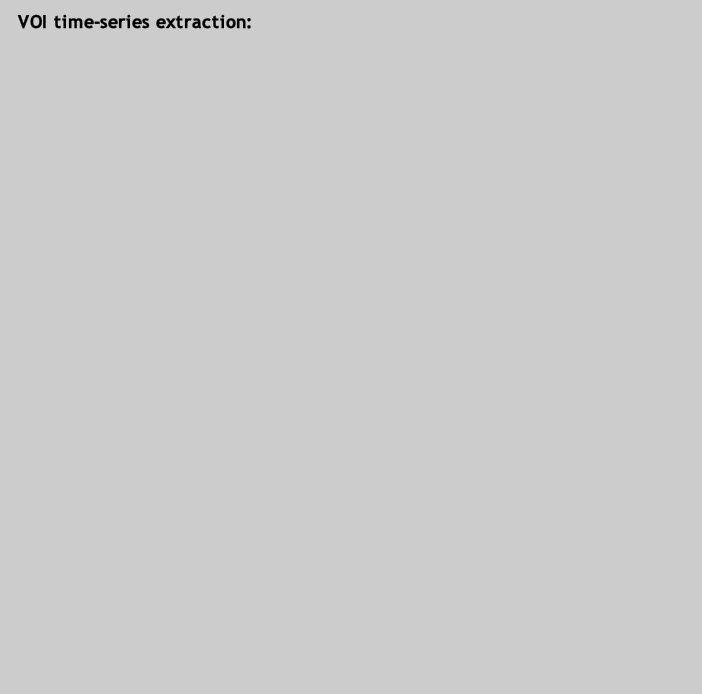

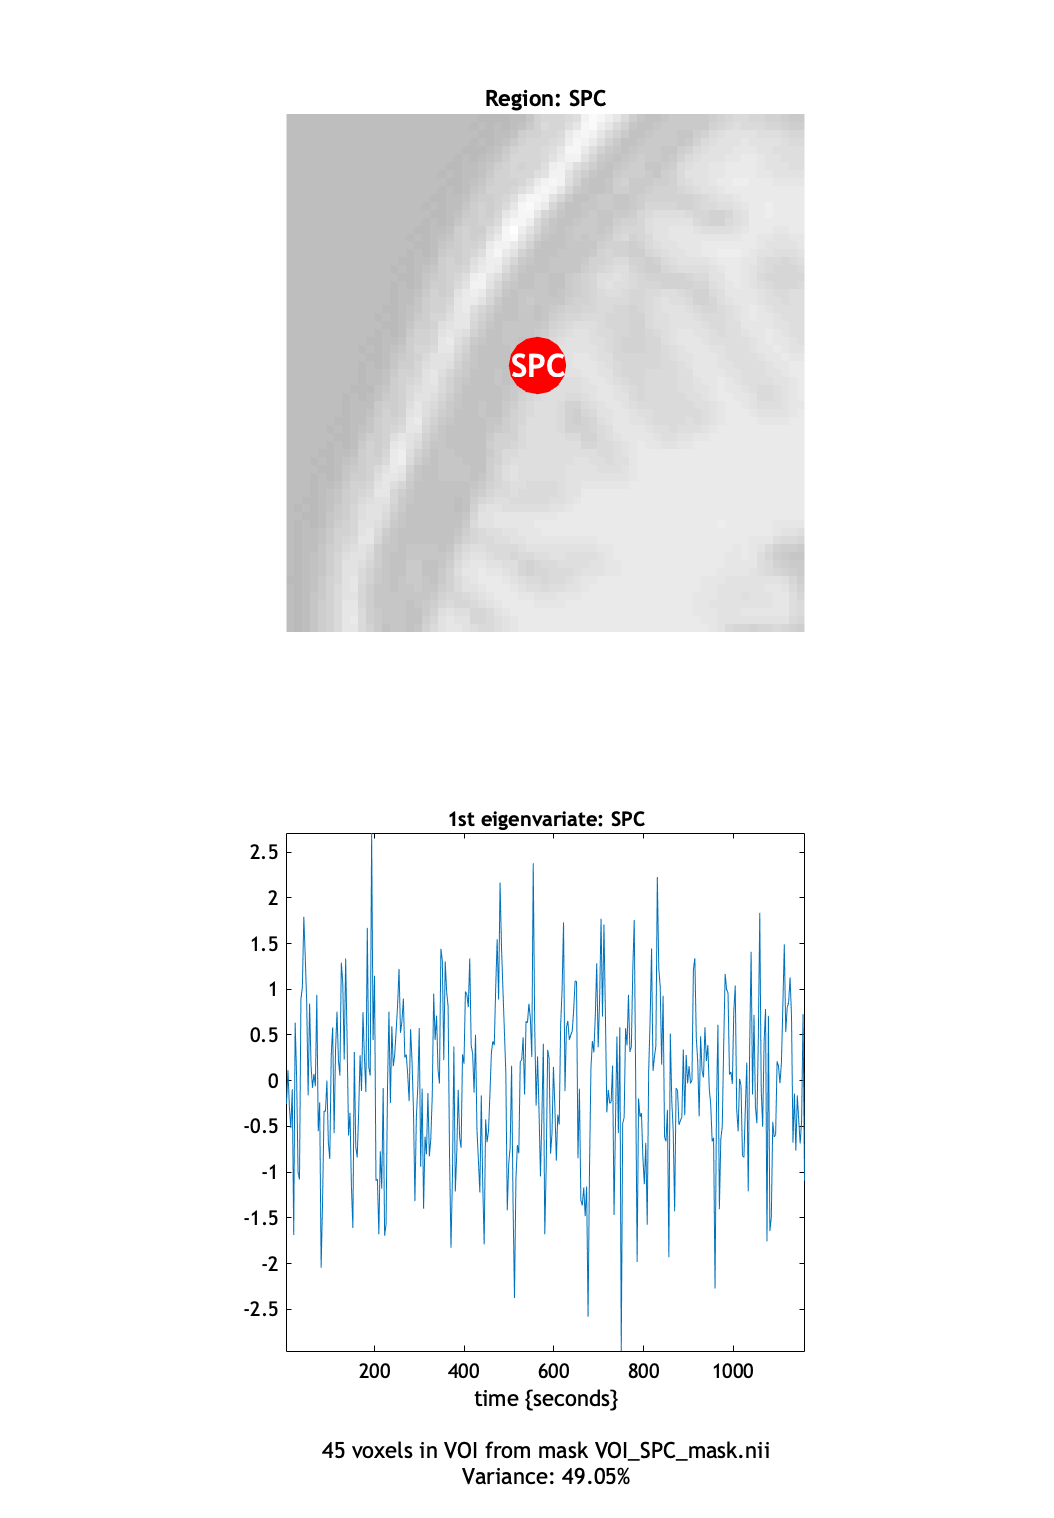



------------------------------------------------------------------------
15-Jul-2025 16:29:24 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 16:29:24 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM1_attention/attention/GLM/VOI_SPC_1.mat


15-Jul-2025 16:29:25 - Done    'Volume of Interest'
15-Jul-2025 16:29:25 - Done



get_VOI(spm_mat_file, fullfile(saveDirGLM,'con_0003.nii'), 'SPC', [-27 -84 36], 8);

## Specify DCM 

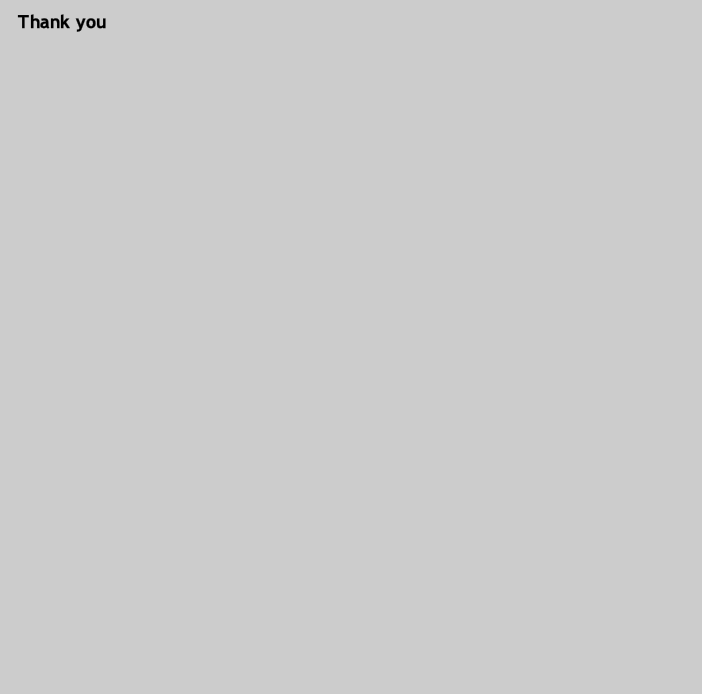

n   = 3;    % number of regions
nu  = 3;    % number of inputs (experimental conditions)
TR  = 3.22;  % volume repetition time (seconds)
TE  = 0.04; % echo time (seconds)

cond = struct();

cond(1).name    = 'Photic'; % Name of condition for the DCM
cond(1).spmname = 'Photic'; % Name of conditions in SPM

cond(2).name    = 'Motion';
cond(2).spmname = 'Motion';

cond(3).name    = 'Attention';               
cond(3).spmname = 'Attention';  

% VOIs
xY = {fullfile(saveDirGLM,'VOI_V1_1.mat');
      fullfile(saveDirGLM,'VOI_V5_1.mat');
      fullfile(saveDirGLM,'VOI_SPC_1.mat');
     };
 
% Average connectivity
a  = [1 1 0;
    1 1 1;
    0 1 1];
  
% Modulatory inputs
b  = zeros(n,n,nu);
b(2,1,2) = 1; % Motion: V1 -> V5
b(2,3,3) = 1; % Attention: SPC -> V5

% Driving inputs
c = zeros(n,nu);
c(:,1) = 1;        % Photic -> V1

% Non-linear connections (not used)
d = zeros(n,n,0);

% DCM settings
s = struct();
s.name       = 'mod_bwd';
s.cond       = cond;
s.delays     = repmat(TR/2, 1, n);
s.TE         = TE;
s.nonlinear  = false;
s.two_state  = false;
s.stochastic = false;
s.centre     = true;
s.induced    = 0;
s.a          = a;
s.b          = b;
s.c          = c;
s.d          = d;

% Specify DCM - model 1 (Backward) 
SPM = fullfile(saveDirGLM,'SPM.mat');
DCM = spm_dcm_specify(SPM,xY,s);

% Specify DCM - model 2 (Forward) 

% Modulatory inputs
b  = zeros(n,n,nu);
b(2,1,2) = 1; % Motion: V1 -> V5
b(2,1,3) = 1; % Attention: SPC -> V5

s.b          = b;
s.name       = 'mod_fwd';

DCM = spm_dcm_specify(SPM,xY,s);

clear DCM;


## DCM model inversion



------------------------------------------------------------------------
15-Jul-2025 16:36:11 - Running job #2
------------------------------------------------------------------------
15-Jul-2025 16:36:11 - Running 'DCM estimation'
Loading DCMs...Done
EM:(+): 1     F: 0.000e+00 dF predicted: 1.747e+03  actual: 1.263e+03 (3.44 sec)
EM:(+): 2     F: 1.263e+03 dF predicted: 2.537e+02  actual: 1.735e+02 (2.95 sec)
EM:(+): 3     F: 1.436e+03 dF predicted: 1.690e+02  actual: 1.529e+02 (3.19 sec)
EM:(+): 4     F: 1.589e+03 dF predicted: 1.528e+02  actual: 1.188e+02 (3.01 sec)
EM:(+): 5     F: 1.708e+03 dF predicted: 8.558e+01  actual: 6.480e+01 (3.09 sec)
EM:(+): 6     F: 1.773e+03 dF predicted: 5.848e+01  actual: 4.776e+01 (3.35 sec)
EM:(+): 7     F: 1.820e+03 dF predicted: 4.782e+01  actual: 4.199e+01 (3.40 sec)
EM:(+): 8     F: 1.862e+03 dF predicted: 4.527e+01  actual: 3.960e+01 (3.45 sec)
EM:(+): 9     F: 1.902e+03 dF predicted: 3.862e+01  actual: 3.200e+01 (3.53 sec)
EM:(+): 10     F:

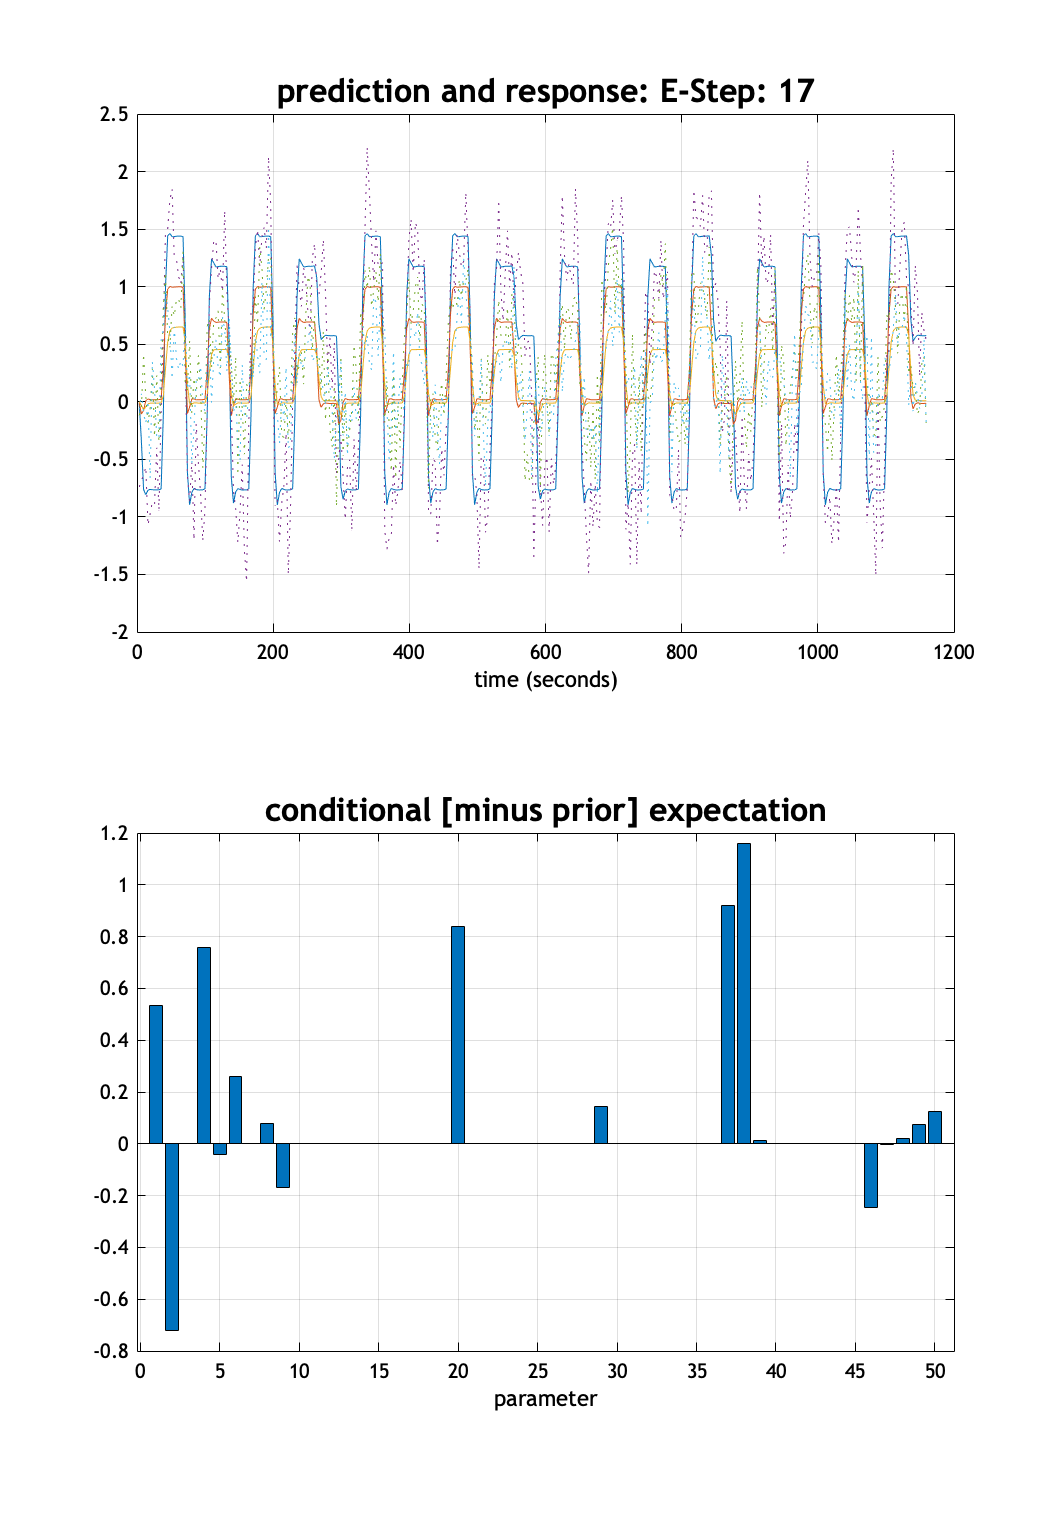

EM:(+): 17     F: 1.961e+03 dF predicted: 2.330e-04  convergence
15-Jul-2025 16:38:33 - Done    'DCM estimation'
15-Jul-2025 16:38:33 - Done



models = {fullfile(saveDirGLM,'DCM_mod_bwd.mat');
          fullfile(saveDirGLM,'DCM_mod_fwd.mat')};

clear matlabbatch
matlabbatch{1}.spm.dcm.fmri.estimate.dcmmat = models;
matlabbatch{1}.spm.dcm.estimate.fmri.analysis = 'time';
spm_jobman('run',matlabbatch);  

## Model Comparison



------------------------------------------------------------------------
15-Jul-2025 17:41:48 - Running job #2
------------------------------------------------------------------------
15-Jul-2025 17:41:48 - Running 'Model Inference'

SPM25: spm_run_dcm_bms                             17:41:48 - 15/07/2025
Loading DCMs for subject 1
Identifying data: model 1
Identifying data: model 2
Computing FFX model/family posteriors   : 

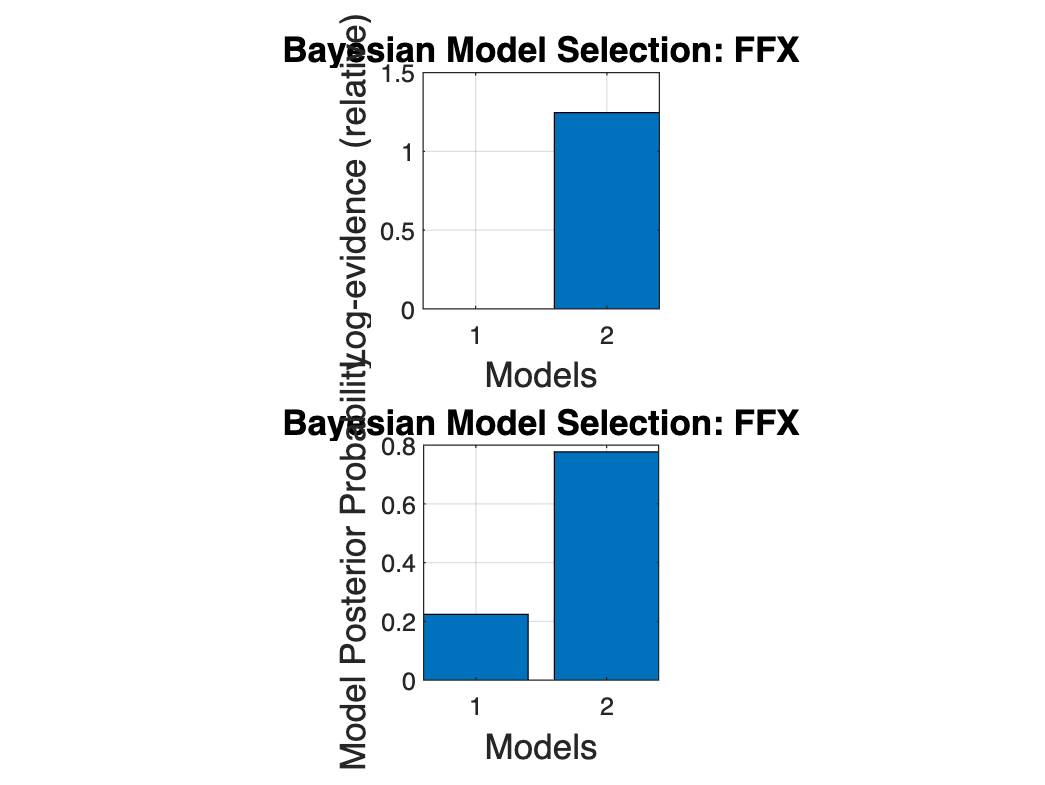

                       ...done
Data identity                           :                    ...verified
Saving BMS.mat                          :                        ...done
Saving model space                      :                        ...done
15-Jul-2025 17:41:52 - Done    'Model Inference'
15-Jul-2025 17:41:52 - Done



dcm_models = {fullfile(saveDirGLM,'DCM_mod_bwd.mat') 
          fullfile(saveDirGLM,'DCM_mod_fwd.mat')};

clear matlabbatch
matlabbatch{1}.spm.dcm.bms.inference.dir = {saveDirGLM};
matlabbatch{1}.spm.dcm.bms.inference.sess_dcm{1}.dcmmat = dcm_models;
matlabbatch{1}.spm.dcm.bms.inference.model_sp = {''};
matlabbatch{1}.spm.dcm.bms.inference.load_f = {''};
matlabbatch{1}.spm.dcm.bms.inference.method = 'FFX';
matlabbatch{1}.spm.dcm.bms.inference.family_level.family_file = {''};
matlabbatch{1}.spm.dcm.bms.inference.bma.bma_no = 0;
matlabbatch{1}.spm.dcm.bms.inference.verify_id = 1;
spm_jobman('run',matlabbatch);  

## Functions

function [] = get_VOI(spm_mat_file, mask_file, VOI_name, centre, radius)

% Start batch
clear matlabbatch;
matlabbatch{1}.spm.util.voi.spmmat = {spm_mat_file};
matlabbatch{1}.spm.util.voi.adjust = 1; % effects
matlabbatch{1}.spm.util.voi.session = 1;
matlabbatch{1}.spm.util.voi.name = VOI_name;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.centre = centre;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.radius = radius;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.move.fixed = 1;
matlabbatch{1}.spm.util.voi.roi{2}.mask.image = {mask_file};
matlabbatch{1}.spm.util.voi.roi{2}.mask.threshold = 0.5;
matlabbatch{1}.spm.util.voi.expression = 'i1&i2';

% Run the batch
spm_jobman('run',matlabbatch);

end